## Using the Quiver function

Say we have these  2-D vectors:

v1 = [3,0];
v2 = [0,6];
v3 = [5,2];

Let's use the [`quiver()`](matlab:  web(fullfile(docroot, 'matlab/ref/quiver.html'))) function to draw each of these vectors on the same graph:

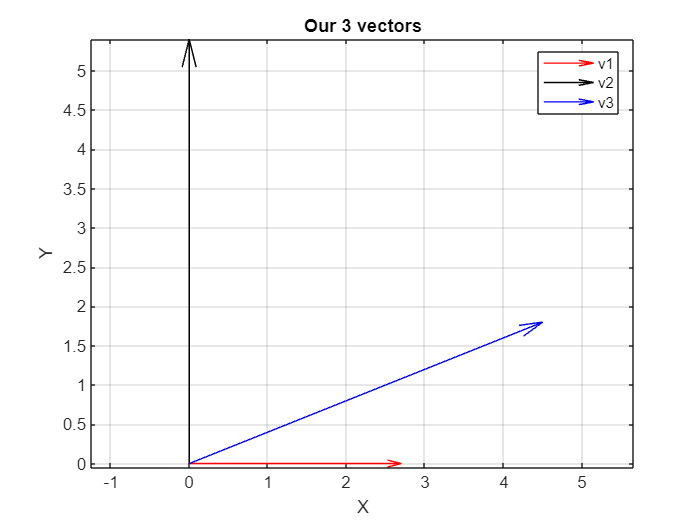

figure;
    quiver( 0,0, v1(1), v1(2), '-r' );
       hold("on")
    quiver( 0,0, v2(1), v2(2), '-k' );
    quiver( 0,0, v3(1), v3(2), '-b' );
    
    axis("equal")
    grid("on")
    xlabel("X")
    ylabel("Y")
    legend(["v1","v2","v3"], "Location", "best")
    title("Our 3 vectors")

Next, let's plot the vector sum of these vectors

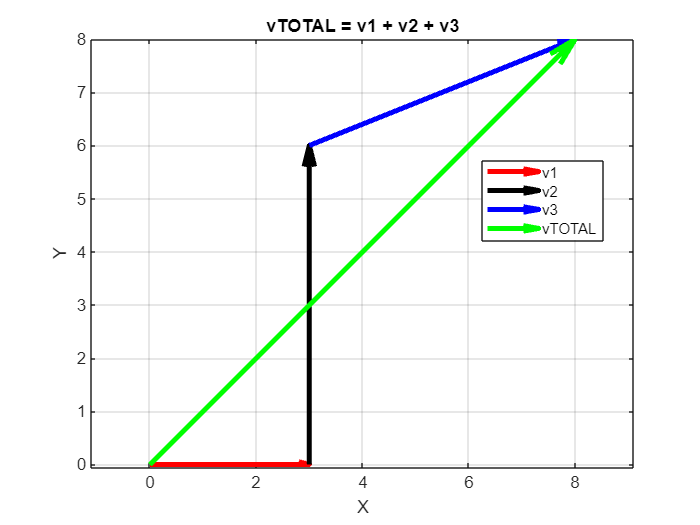

figure
    % plot v1
    xy_start_point = [0,0];
    the_vec        = v1;
    quiver(xy_start_point(1), xy_start_point(2),  the_vec(1), the_vec(2), 'off', 'r',  "LineWidth",3);   
    
    hold("on")

    % plot v2
    xy_start_point = v1;
    the_vec        = v2;
    quiver(xy_start_point(1), xy_start_point(2),  the_vec(1), the_vec(2), 'off', 'k',  "LineWidth",3);  
    
    % plot v3
    xy_start_point = v1 + v2;
    the_vec        = v3;
    quiver(xy_start_point(1),xy_start_point(2),   the_vec(1), the_vec(2),  'off',   'b', "LineWidth",3);  
    
    % plot vtotal    
    xy_start_point = [0,0];
    the_vec        = v1+v2+v3;
    quiver(xy_start_point(1),xy_start_point(2),   the_vec(1), the_vec(2),  'off',   'g', "LineWidth",3);  

        axis("equal")
        grid("on")
        xlabel("X")
        ylabel("Y")
        legend(["v1","v2","v3", "vTOTAL"], "Location", "best")
        title("vTOTAL = v1 + v2 + v3")